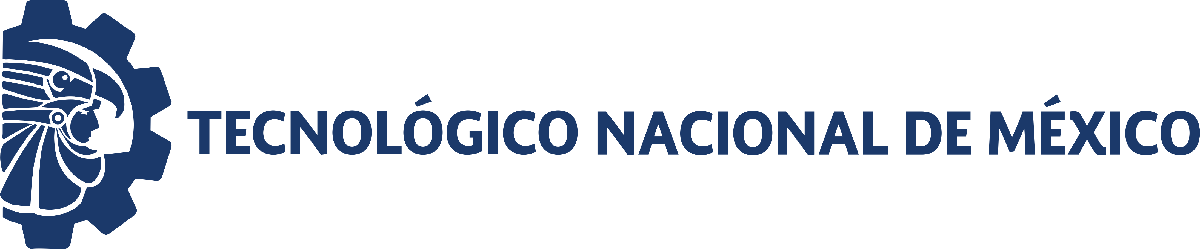                                 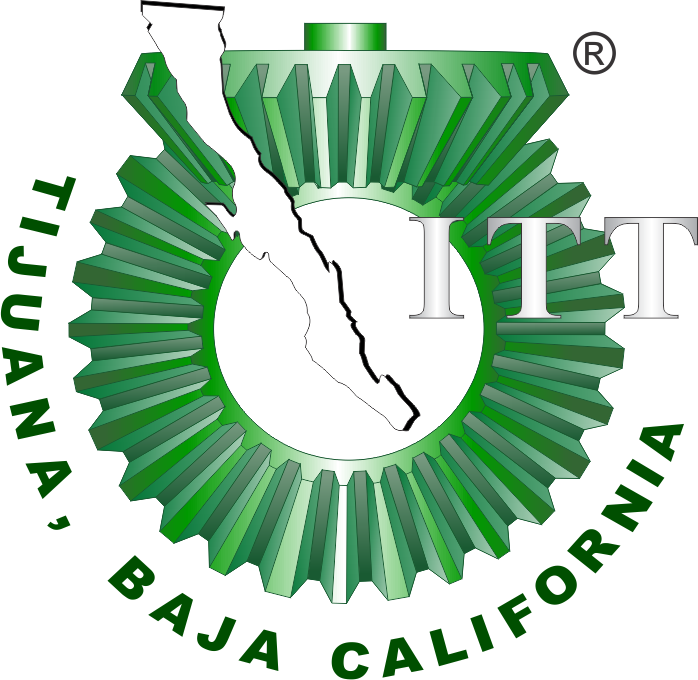

# Práctica cuatro: Sistema endocrino

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

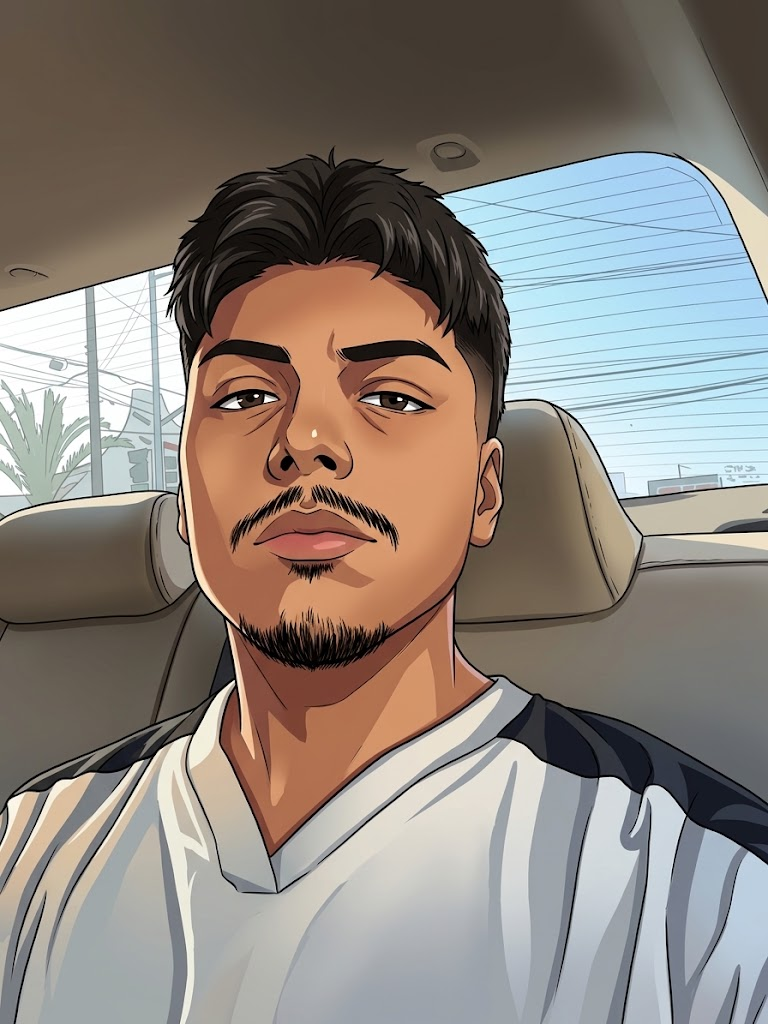

Nombre del alumno: David Emiliano Diaz de Leon Bernal

Número de control: C23211564

Correo institucional: l23211564@tectijuana.edu.mx

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
clc; clear; close all; warning('off','all')
open_system("practica4.slx")
parameters.Stoptime='10';
parameters.Solver='ode15s';
parameters.Maxstep='1e-3';
x = sim('practica4',parameters);

## Respuesta Control,Caso y Tratamiento

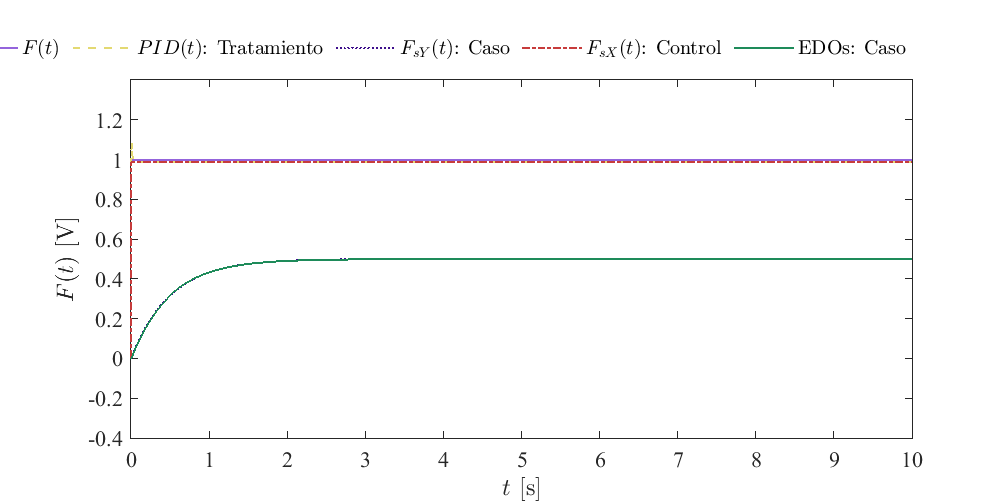

plotsignals(x.t, x.F, x.PID, x.Fsy, x.Fsx, x.Caso, 'CCT')

## Funcion: Respuestas de la simulacion

function plotsignals (t,x1,x2,x3,x4,x5,signal)
    set(figure(),'color','w')
    set(gcf,'units','inches','position',[1,1,7,3.5])
    set(gca,'fontname','times new roman','fontsize',11)
    hold on; grid off; box on;
    clr1 = [149, 100, 221]/256;
    clr2 = [228, 218, 114]/256;
    clr3 = [62, 15, 141]/256;
    clr4 = [200, 60, 60]/256;
    clr5 = [ 30, 140,  90]/256;
    colororder([clr1;clr2;clr3;clr4;clr5])

    if signal == "CCT"
        plot(t,x1,'-', t,x2,'--', t,x3,':', t,x4,'-.',t,x5,'-','LineWidth',1)
        L = legend('$F(t)$','$PID(t)$: Tratamiento','$F_{sY}(t)$: Caso','$F_{sX}(t)$: Control','EDOs: Caso');

    end

    set(L,'interpreter','latex','location','northoutside','orientation','horizontal','box','off')

    xlabel('$t$ [s]','Interpreter','latex')
    ylabel('$F(t)$ [V]','Interpreter','latex')

    xlim([0 10]); xticks(0:1:10)
    ylim([-0.4 1.4]); yticks(-0.4:0.2:1.2)

    exportgraphics(gcf,[signal,'_matlab.pdf'],'ContentType','vector')
end